# 模拟退火

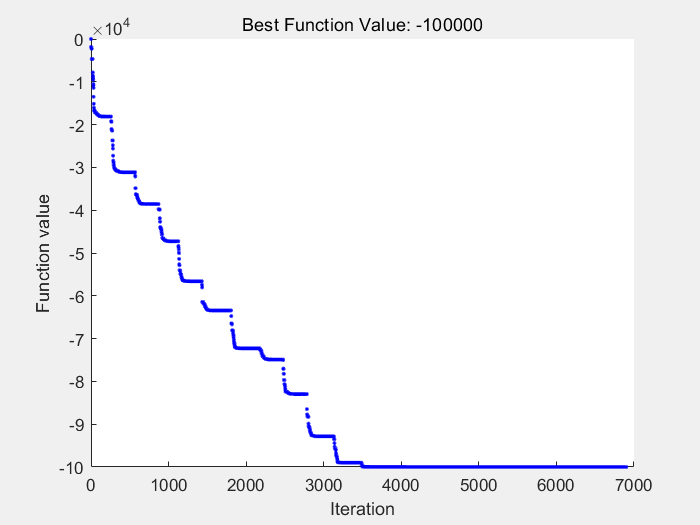

Optimization terminated: change in best function value less than options.FunctionTolerance.


x0 = [1 1 1];
x_lb = [0 0 0];
x_ub = [100 100 1000];
options = optimoptions("simulannealbnd","PlotFcn","saplotbestf");

[x, fval, exitflag, output] = simulannealbnd(@Obj_fun, x0, x_lb, x_ub, options);

x, fval

x = 	1.0e+03 *

    0.0000    0.1000    1.0000


fval = -100000

## 函数定义

function y = Obj_fun(x)
    y = x(1)^2 - x(2)*x(3);
end